clc
clear

# **Kmeans**

### a) Generate a 2D uncorrelated Gaussian distributed training dataset

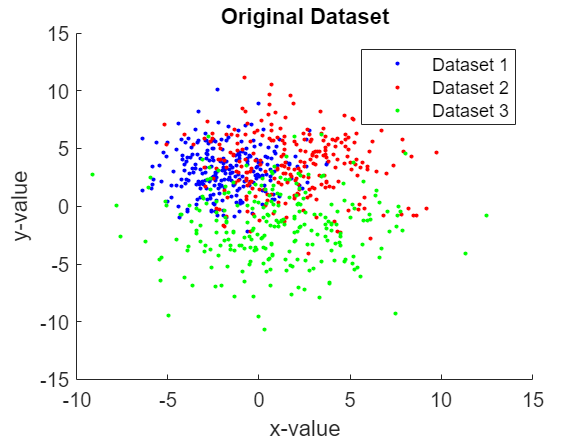

samples = 250;

%cluster 1 
mean1 = [-2; 3];
sd1 = 2;

%cluster 2
mean2 = [2; 4];
sd2 = 3;

%cluster 3
mean3 = [1; -2];
sd3 = 3.25;

dataset1 = sd1 * randn(2,samples) + repmat(mean1,1,samples);
dataset2 = sd2 * randn(2,samples) + repmat(mean2,1,samples);
dataset3 = sd3 * randn(2,samples) + repmat(mean3,1,samples);

%plot
hold on
plot(dataset1(1,:),dataset1(2,:),'b.')
plot(dataset2(1,:),dataset2(2,:),'r.')
plot(dataset3(1,:),dataset3(2,:),'g.')
xlabel('x-value')
ylabel('y-value')
title("Original Dataset")
legend('Dataset 1','Dataset 2','Dataset 3')
hold off

### b) Concatenate the datasets into a single dataset and plot all the points

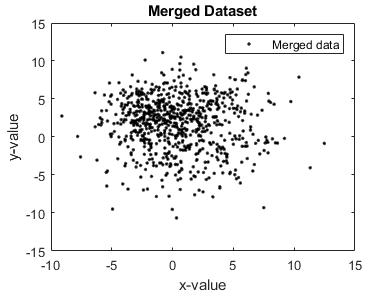

ConCluster = cat(2,dataset1,dataset2,dataset3);

plot(ConCluster(1,:),ConCluster(2,:),'black.')
title("Merged Dataset")
legend('Merged data')
xlabel('x-value')
ylabel('y-value')

### c) Given the number of clusters as 3, implement Kmeans clustering from first principles

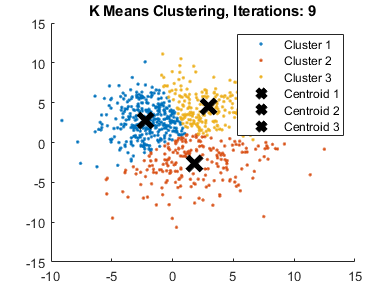

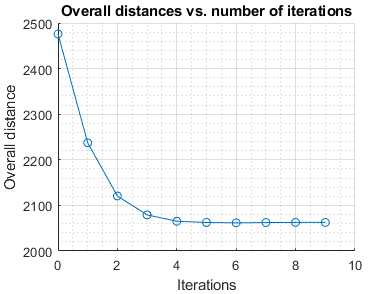

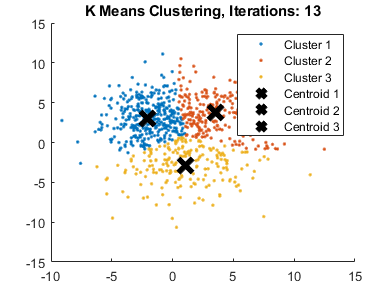

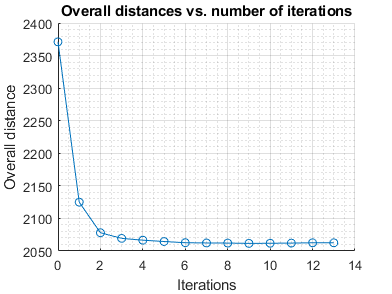

k = 3;
maxIterations = 2;
a = kmeansClustering(ConCluster,k,maxIterations,true);

%calcVariation(a,k,true);

### d) If the number of clusters is unknown, explain and find out (via matlab code) the best number of clusters.

k = 10

k = 10

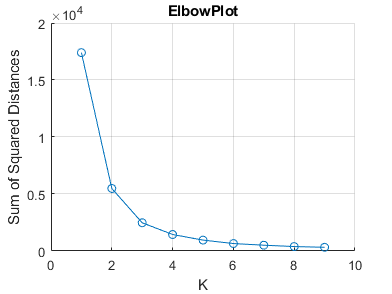

elbowPlot(ConCluster,k);

### e) From  your  observation  and  analysis,  what  are  the  limitations  or  drawbacks  of  Kmeans clustering?  

### Functions:

#### Elbow Plot function

function elbowPlot(ConCluster, max_K)
    allVari = [];
    for k = 1:max_K
        totalVari = 0;
        clustInfo = kmeansClustering(ConCluster,k,1,false);
        sumSqu = calcSumSquDists(clustInfo,k,false);
        if(size(sumSqu,2) ~=0)
            for i = 1:k
                totalVari = totalVari + sumSqu(i);
            end
            allVari = [allVari,[totalVari;k]];
        end
    end
    figure    
    hold on
    xlabel('K')
    ylabel('Sum of Squared Distances')
    plot(allVari(2,:),allVari(1,:),"o-")
    title('ElbowPlot')
    grid on
    hold off
end

#### K means clustering

function [results] = kmeansClustering(ConCluster,k,max_iterations,graphOn)
    %select the number of clusters you want to identify in your data.
    %this is the k in k-means clustering
    %k=3;
    %max_iterations = 5;
    groupedClusters = [];%x;y;centroid;iteration;bestDistance

    for j = 1:max_iterations
        done = false;
        iteration=0;
    
        centroidArray = [];
        newCentroidArray = [];
        distArray = [];
        clusterArray = [];
    
        %testing vars
        totalDistance=0;
        totalDistances = [];
    
        %step2 randomly select 3 destinct datapoints -> these are the initical clusters
        for cen = 1:k
            r = (randi([1,size(ConCluster,2)],1));
            centroid = [ConCluster(1,r);ConCluster(2,r)];
            centroidArray = [centroidArray, centroid];
        end
        for i  = 1:size(ConCluster,2)
            distArray = [];
            %step 3 Measure the distances between the 1st point and the three initial
            %clusters
    
            %loop through centroidArray
            for cen = 1:k
                %calculate distance from each point
                %dist = sqrt((centroid1(1,1)-ConCluster(1,i))^2+(centroid1(2,1)-ConCluster(2,i))^2);
                dist = sqrt((centroidArray(1,cen)-ConCluster(1,i))^2+(centroidArray(2,cen)-ConCluster(2,i))^2);
                %save distance in distance array
                distArray = [distArray,dist];
            end
            %step 4 Assign the first point to the nearest cluster -> do the same for
            %the next point
            %-> measure the distances and assign the point to the nearest cluster
            for d = 1:k
                d;
                %check if first distance
                if d == 1
                    %save distance for next iteration
                    bestDist = distArray(d);
                    bestCentNum = d;
                else
                    %get distance
                    curDist = distArray(d);
                    %compare with old distance
                    if bestDist > curDist
                        %bestDist
                        bestDist = curDist;
                        bestCentNum = d;
                    end
                end
            end
            totalDistance = totalDistance + bestDist;
    
            %assign point to nearest cluster
            [ConCluster(1,i);ConCluster(2,i);bestCentNum];
            clusterArray = [clusterArray, [ConCluster(1,i);ConCluster(2,i);bestCentNum]];
        end
    
        totalDistances = [totalDistances,[iteration;totalDistance]];
    
        while done==false
            bDistances = [];
            iteration = iteration +1;
            totalDistance = 0;
            %step 5 calculate the mean of each cluster
            %repeat what just did (measure and cluster) using the mean values
            %sum of rows
            newCentroidArray = [];
            %calculate mean of each cluster
            for cen = 1:k
                %get cluster(cen)
                clustIdxs = find(clusterArray(3,:)==cen);
                clust = clusterArray(:,clustIdxs);
                %calc mean of that cluster and add to newClusterArray
                clustSize = size(clust,2);
                newCentroidArray = [newCentroidArray,[(sum(clust(1,:)))/clustSize;(sum(clust(2,:)))/clustSize]];
            end
            clusterArray = [];
            newCentroidArray;
            for i  = 1:size(ConCluster,2)
                %set reset distArray
                distArray = [];
                %loop through centroidArray
                for cen = 1:k
                    %calculate distance from each point
                    dist = sqrt((newCentroidArray(1,cen)-ConCluster(1,i))^2+(newCentroidArray(2,cen)-ConCluster(2,i))^2);
                    %save distance in distance array
                    distArray = [distArray,dist];
                end
                for d = 1:k
                    %check if first distance
                    if d == 1
                        %save distance for next iteration
                        bestDist = distArray(d);
                        bestCentNum = d;
                    else
                        %get distance
                        curDist = distArray(d);
                        %compare with old distance
                        if bestDist > curDist
                            %bestDist
                            bestDist = curDist;
                            bestCentNum = d;
                        end
                    end
                end
                totalDistance = totalDistance + bestDist;
                bDistances = [bDistances,bestDist];
                %assign point to nearest cluster
                clusterArray = [clusterArray, [ConCluster(1,i);ConCluster(2,i);bestCentNum]];
    
            end
            %clusterArray
            totalDistances = [totalDistances,[iteration;totalDistance]];
            totalDistance=0;
    
            %if clustering does not change during iteration then k-means is complete
            if (centroidArray == newCentroidArray)% finish !!!!!!!!!!!!!
                %stop
                iteration;
                done=true;
                if graphOn
                figure
                hold on
                for cen = 1:k
                    %get cluster(cen)
                    clustIdxs = find(clusterArray(3,:)==cen);
                    clust = clusterArray(:,clustIdxs);
                    %plot on graph
                    pointName = append('Cluster ',int2str(cen));
                    plot(clust(1,:),clust(2,:),'.','DisplayName',pointName)
                    legend()
                end
                %centroidArray
                for cen = 1:k
                    newCentroidArray;
                    pointName = append('Centroid ',int2str(cen));
                    plot(newCentroidArray(1,cen),newCentroidArray(2,cen),'black x','MarkerSize',15,'linewidth',4,'DisplayName',pointName)
                end
                titleName = append('K Means Clustering, Iterations: ',int2str(iteration));
                title(titleName)
                hold off
    
                %plot distances and iterations
                figure
                hold on
                xlabel('Overall distances')
                ylabel('Iterations')
                plot(totalDistances(1,:),totalDistances(2,:),'o-')
                grid on
                grid minor
                xlabel('Iterations')
                ylabel('Overall distance')
                title('Overall distances vs. number of iterations')
                hold off
                end
                totalDistances = [];
                
                iteratoinMatrix = zeros(1,size(clusterArray,2));
                iteratoinMatrix(1,:) = iteration;
                clustWIt = cat(1,clusterArray, iteratoinMatrix);
                clustWIt = cat(1,clustWIt, bDistances);
                

                %groupedClusters = [groupedClusters,clustWIt]

                %attempting 3d matrix
                groupedClusters=cat(3,groupedClusters,clustWIt);
    
            else
                %continue
                done = false;
    
                centroidArray = newCentroidArray;
                %newCentroidArray = [];
                if iteration == 1500%Give up after 1500 iterations
                    done = true;
                end
            end
        end
    
    end
    results = groupedClusters;
end

%can assess the quality of the clustering by adding up the variation within
%each cluster

%keep track of these clusters and their total varience and do the whole
%thing over with different starting points

#### Variance function

function [totalVariationArray] = calcVariation(a,kValue,graphOn)
    totalVariationArray = [];
    %loop through every kmeans dataset
    for d = 1:size(a,3)
        a;
        totalVariations = [];
        %seperate centroids
        for cen = 1:kValue
            d;
            b = 0;
            clustIdxs = find(a(3,:,d)==cen);
            clust = a(:,clustIdxs);
            for i = 1:size(clust,2)
                b = b + ((clust(5,i)-mean(clust(5,:)))^2);
            end
            variation = b/size(clust,2);
            totalVariations = [totalVariations; variation];
        end
        totalVariationArray = [totalVariationArray,totalVariations];
    end
    %figure
    totalVariationArray = totalVariationArray'
    if graphOn
        bar(totalVariationArray,'stacked')
    end
end



function [sumSquDist] = calcSumSquDists(a,kValue,graphOn)
    sumSquDist = [];
    %for d = 1:size(a,3)
    %    a(:,:,d)
    %end
    %loop through every kmeans dataset
    for d = 1:size(a,3)
        a;
        totalSquDist = [];
        %seperate centroids
        %z = size(a,3)
        y = size(a,2);
        %x = size(a,3)
        if (y ~= 0)
            for cen = 1:kValue
                d;
                b = 0;
                clustIdxs = find(a(3,:,d)==cen);
                clust = a(:,clustIdxs);
                for i = 1:size(clust,2)
                    %b = b + ((clust(5,i)-mean(clust(5,:)))^2);
                    clust(5,i);
                    b = b + (clust(5,i))^2;
                end
                b;
                %vvv = size(clust,2)
                %squDist = b/size(clust,2);
                squDist = b/kValue;
                totalSquDist = [totalSquDist; squDist];
            end
        end
        sumSquDist = [sumSquDist,totalSquDist];
    end
    %figure
    %sumSquDist = sumSquDist'
    if graphOn
        bar(sumSquDist,'stacked')
    end
end